%%1
t = 10;
num = randi([1, 5], 1, t);
prob_odd_count_10 = sum(mod(num,2))/t

prob_odd_count_10 = 0.8000


t = 50;
num = randi([1, 5], 1, t);
prob_odd_count_50 = sum(mod(num,2))/t

prob_odd_count_50 = 0.5600


t = 100;
num = randi([1, 5], 1, t);
prob_odd_count_100 = sum(mod(num,2))/t

prob_odd_count_100 = 0.6600


t = 500;
num = randi([1, 5], 1, t);
prob_odd_count_500 = sum(mod(num,2))/t

prob_odd_count_500 = 0.6020


t = 1000;
num = randi([1, 5], 1, t);
prob_odd_count_1000 = sum(mod(num,2))/t

prob_odd_count_1000 = 0.5910


%1,3,5
math_analy_prob_odd = 3/5

math_analy_prob_odd = 0.6000


%d
P = [2/7, 2/7, 1/7, 1/7, 1/7];

t = 10;
outcomes = randsample(1:5, t, true, P);
d_prob_odd_count_10 = sum(mod(outcomes,2))/t

d_prob_odd_count_10 = 0.9000


t = 50;
outcomes = randsample(1:5, t, true, P);
d_prob_odd_count_50 = sum(mod(outcomes,2))/t

d_prob_odd_count_50 = 0.5200


t = 100;
outcomes = randsample(1:5, t, true, P);
d_prob_odd_count_100 = sum(mod(outcomes,2))/t

d_prob_odd_count_100 = 0.5000


t = 500;
outcomes = randsample(1:5, t, true, P);
d_prob_odd_count_500 = sum(mod(outcomes,2))/t

d_prob_odd_count_500 = 0.5780


t = 1000;
outcomes = randsample(1:5, t, true, P);
d_prob_odd_count_1000 = sum(mod(outcomes,2))/t

d_prob_odd_count_1000 = 0.5480


%P = [2/7, 2/7, 1/7, 1/7, 1/7];
% 1,2,3
d_math_analy_prob_odd = (2+1+1)/7

d_math_analy_prob_odd = 0.5714

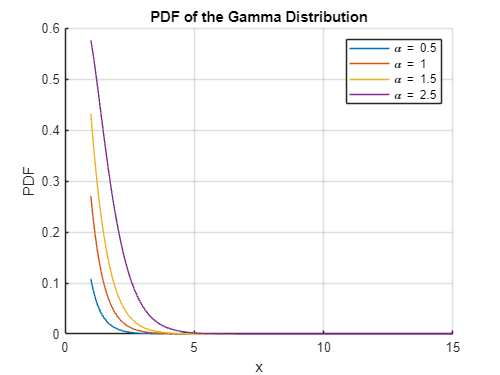

%%2
x = linspace(1, 15, 1000);
figure;
hold on;
title('PDF of the Gamma Distribution');
xlabel('x');
ylabel('PDF');
grid on;

lambda = 0.5;
alpha_values = [0.5, 1, 1.5, 2.5];


alpha = alpha_values(1);
pdf = gampdf(x, alpha, lambda); % Compute PDF
plot(x, pdf, 'DisplayName', ['\alpha = ', num2str(alpha)]);
alpha = alpha_values(2);
pdf = gampdf(x, alpha, lambda); % Compute PDF
plot(x, pdf, 'DisplayName', ['\alpha = ', num2str(alpha)]);
alpha = alpha_values(3);
pdf = gampdf(x, alpha, lambda); % Compute PDF
plot(x, pdf, 'DisplayName', ['\alpha = ', num2str(alpha)]);
alpha = alpha_values(4);
pdf = gampdf(x, alpha, lambda); % Compute PDF
plot(x, pdf, 'DisplayName', ['\alpha = ', num2str(alpha)]);
legend show;
hold off;

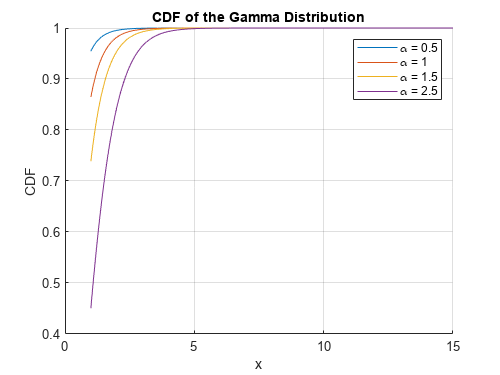


figure;
hold on;
title('CDF of the Gamma Distribution');
xlabel('x');
ylabel('CDF');
grid on;
alpha = alpha_values(1);
cdf = gamcdf(x, alpha, lambda); % Compute CDF
plot(x, cdf, 'DisplayName', ['\alpha = ', num2str(alpha)]);
alpha = alpha_values(2);
cdf = gamcdf(x, alpha, lambda); % Compute CDF
plot(x, cdf, 'DisplayName', ['\alpha = ', num2str(alpha)]);
alpha = alpha_values(3);
cdf = gamcdf(x, alpha, lambda); % Compute CDF
plot(x, cdf, 'DisplayName', ['\alpha = ', num2str(alpha)]);
alpha = alpha_values(4);
cdf = gamcdf(x, alpha, lambda); % Compute CDF
plot(x, cdf, 'DisplayName', ['\alpha = ', num2str(alpha)]);
legend show;
hold off;


%c
t = 100

t = 100

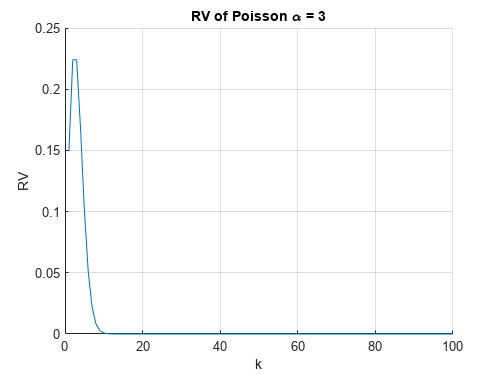

k = linspace(1, t, t);
alpha_values = [3, 25, 100];

figure;
hold on;
title('RV of Poisson \alpha = 3');
xlabel('k');
ylabel('RV');
grid on;
alpha = alpha_values(1);
Poisson_RV = (alpha.^k).*exp(-alpha)./factorial(k);
plot(k, Poisson_RV, 'DisplayName', ['\alpha = ', num2str(alpha)]);
hold off;

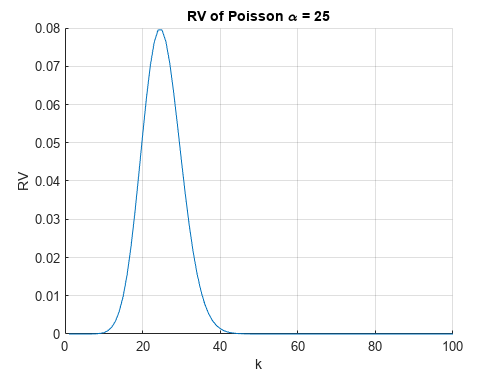


figure;
hold on;
title('RV of Poisson \alpha = 25');
xlabel('k');
ylabel('RV');
grid on;
alpha = alpha_values(2);
Poisson_RV = (alpha.^k).*exp(-alpha)./factorial(k);
plot(k, Poisson_RV, 'DisplayName', ['\alpha = ', num2str(alpha)]);
hold off;

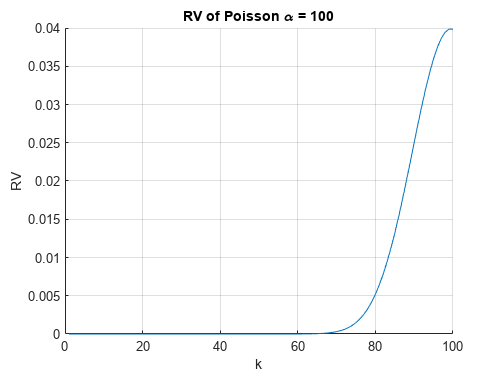


figure;
hold on;
title('RV of Poisson \alpha = 100');
xlabel('k');
ylabel('RV');
grid on;
alpha = alpha_values(3);
Poisson_RV = (alpha.^k).*exp(-alpha)./factorial(k);
plot(k, Poisson_RV, 'DisplayName', ['\alpha = ', num2str(alpha)]);
hold off;

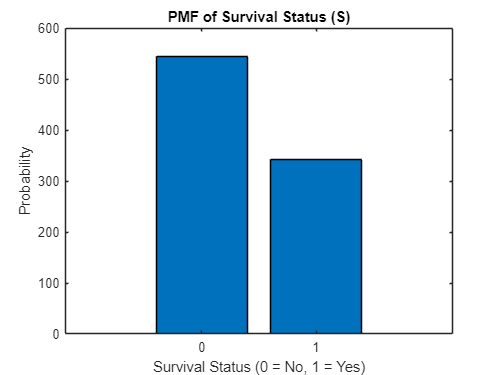

%3
data = readtable('modified_titanic.xlsx');
S = data.Survived;
C = data.Pclass;
G = data.Sex;
A = data.Age;

n=887;

pmf_S = histcounts(S);
figure;
x = 0:1:1;
bar(x,pmf_S);
title('PMF of Survival Status (S)');
xlabel('Survival Status (0 = No, 1 = Yes)');
ylabel('Probability');

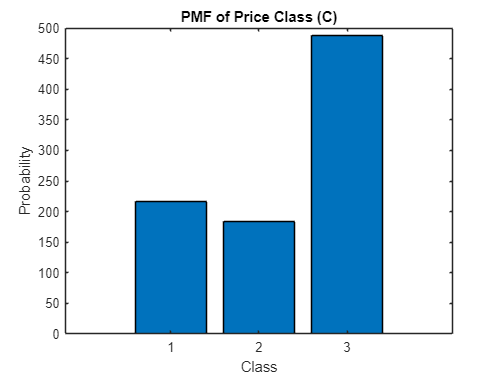


pmf_C = histcounts(C);
figure;
bar(pmf_C);
x = 1:3:3;
title('PMF of Price Class (C)');
xlabel('Class');
ylabel('Probability');

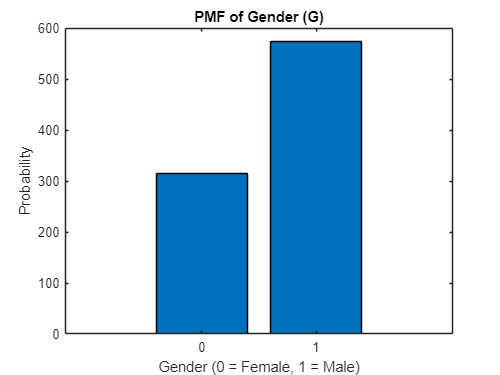


pmf_G = histcounts(G);
figure;
x = 0:1:1;
bar(x,pmf_G);
title('PMF of Gender (G)');
xlabel('Gender (0 = Female, 1 = Male)');
ylabel('Probability');

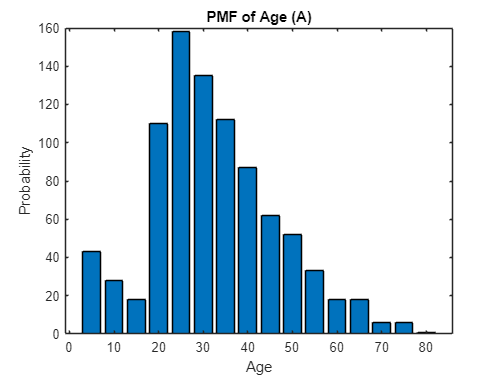


[pmf_A,edges] = histcounts(A);
figure;
bar(edges(2:length(edges)),pmf_A);
title('PMF of Age (A)');
xlabel('Age');
ylabel('Probability');


%Survived
SCount = 0;
for i = 1:n
    if data.Survived(i) == 1
        SCount = SCount + 1;
    end
end
P_SCount = SCount/n

P_SCount = 0.3856


PClass1_Count=0;
for i = 1:n
    if data.Survived(i) == 1 && data.Pclass(i) == 1
        PClass1_Count = PClass1_Count + 1;
    end
end
P_PClass_Count(1) = PClass1_Count/SCount

P_PClass_Count = 0.3977


PClass2_Count=0;
for i = 1:n
    if data.Survived(i) == 1 && data.Pclass(i) == 2
        PClass2_Count = PClass2_Count + 1;
    end
end
P_PClass_Count(2) = PClass2_Count/SCount

P_PClass_Count =     0.3977    0.2544



PClass3_Count=0;
for i = 1:n
    if data.Survived(i) == 1 && data.Pclass(i) == 3
        PClass3_Count = PClass3_Count + 1;
    end
end
P_PClass_Count(3) = PClass3_Count/SCount

P_PClass_Count =     0.3977    0.2544    0.3480



GCount=0;
for i = 1:n
    if data.Survived(i) == 1 && data.Sex(i) == 0
        GCount = GCount + 1;
    end
end
P_GCount(1) = GCount/SCount

P_GCount = 0.6813


GCount=0;
for i = 1:n
    if data.Survived(i) == 1 && data.Sex(i) == 1
        GCount = GCount + 1;
    end
end
P_GCount(2) = GCount/SCount

P_GCount =     0.6813    0.3187





max_age = 80;
age_bin = 5;
P_ACount(max_age/age_bin) = 0;
for j = 1:max_age/age_bin
    ACount = 0;
    min_age_bin = j*5-5;
    max_age_bin = j*5;
    for i = 1:n
        if data.Survived(i) == 1 && data.Age(i) > min_age_bin && data.Age(i) <= max_age_bin
            ACount = ACount + 1;
        end
    end
    P_ACount(j) = ACount/SCount;
end
P_ACount

P_ACount =     0.0965    0.0234    0.0322    0.1199    0.1550    0.1491    0.1404    0.0936    0.0614    0.0643    0.0292    0.0205    0.0117         0         0    0.0029



%Not Survived
SCount_n = 0;
for i = 1:n
    if data.Survived(i) == 0
        SCount_n = SCount_n + 1;
    end
end
P_SCount_n = SCount_n/n

P_SCount_n = 0.6144


PClass1_Count_n=0;
for i = 1:n
    if data.Survived(i) == 0 && data.Pclass(i) == 1
        PClass1_Count_n = PClass1_Count_n + 1;
    end
end
P_PClass_Count_n(1) = PClass1_Count_n/SCount_n

P_PClass_Count_n = 0.1468


PClass2_Count_n=0;
for i = 1:n
    if data.Survived(i) == 0 && data.Pclass(i) == 2
        PClass2_Count_n = PClass2_Count_n + 1;
    end
end
P_PClass_Count_n(2) = PClass2_Count_n/SCount_n

P_PClass_Count_n =     0.1468    0.1780



PClass3_Count_n=0;
for i = 1:n
    if data.Survived(i) == 0 && data.Pclass(i) == 3
        PClass3_Count_n = PClass3_Count_n + 1;
    end
end
P_PClass_Count_n(3) = PClass3_Count_n/SCount_n

P_PClass_Count_n =     0.1468    0.1780    0.6752



GCount_n=0;
for i = 1:n
    if data.Survived(i) == 0 && data.Sex(i) == 0
        GCount_n = GCount_n + 1;
    end
end
P_GCount_n(1) = GCount_n/SCount_n

P_GCount_n = 0.1486


GCount_n=0;
for i = 1:n
    if data.Survived(i) == 0 && data.Sex(i) == 1
        GCount_n = GCount_n + 1;
    end
end
P_GCount_n(2) = GCount_n/SCount_n

P_GCount_n =     0.1486    0.8514




P_ACount_n(max_age/age_bin) = 0;
max_age = 80;
age_bin = 5;
for j = 1:max_age/age_bin
    ACount_n = 0;
    min_age_bin = j*5-5;
    max_age_bin = j*5;
    for i = 1:n
        if data.Survived(i) == 0 && data.Age(i) > min_age_bin && data.Age(i) <= max_age_bin
            ACount_n = ACount_n + 1;
        end
    end
    P_ACount_n(j) = ACount_n/SCount_n;
end
P_ACount_n

P_ACount_n =     0.0294    0.0294    0.0183    0.1596    0.1945    0.1706    0.0954    0.0954    0.0679    0.0477    0.0294    0.0239    0.0220    0.0092    0.0073         0


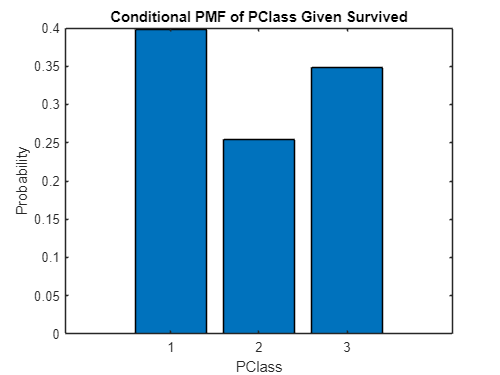


figure;
x = 1:1:3;
bar(x,P_PClass_Count);
title('Conditional PMF of PClass Given Survived');
xlabel('PClass');
ylabel('Probability');

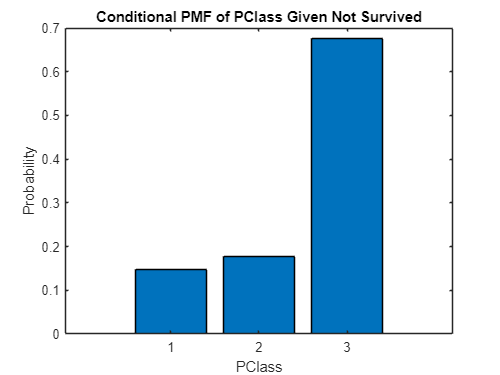


figure;
x = 1:1:3;
bar(x,P_PClass_Count_n);
title('Conditional PMF of PClass Given Not Survived');
xlabel('PClass');
ylabel('Probability');

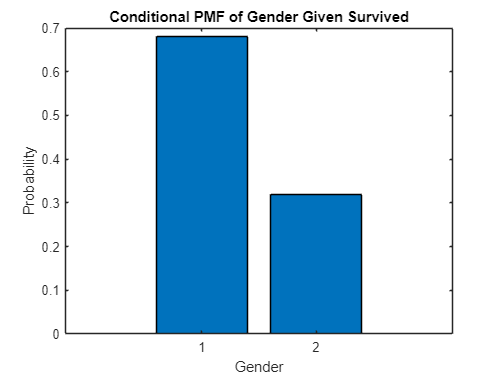


figure;
x = 1:1:2;
bar(x,P_GCount);
title('Conditional PMF of Gender Given Survived');
xlabel('Gender');
ylabel('Probability');

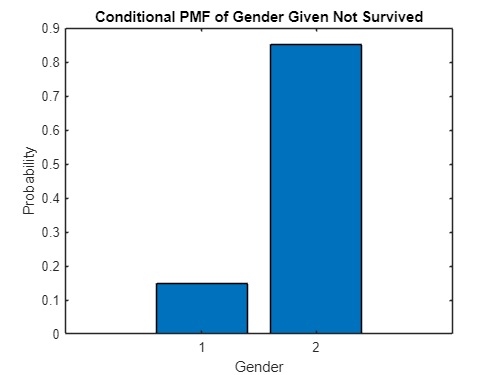


figure;
x = 1:1:2;
bar(x,P_GCount_n);
title('Conditional PMF of Gender Given Not Survived');
xlabel('Gender');
ylabel('Probability');

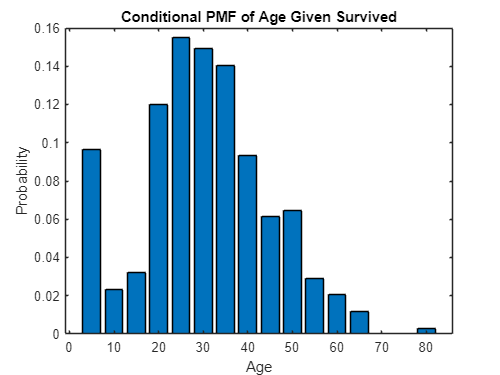


figure;
bar(edges(2:length(edges)),P_ACount);
title('Conditional PMF of Age Given Survived');
xlabel('Age');
ylabel('Probability');

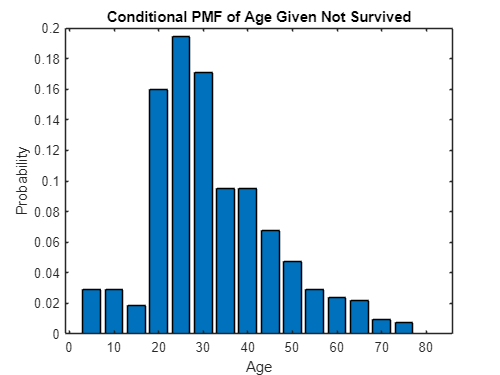


figure;
bar(edges(2:length(edges)),P_ACount_n);
title('Conditional PMF of Age Given Not Survived');
xlabel('Age');
ylabel('Probability');


%c
P_S1_Alteq40 = sum(P_ACount(1:8))

P_S1_Alteq40 = 0.8099

P_S1_C1 = P_PClass_Count(1)

P_S1_C1 = 0.3977

P_S1_G0 = P_GCount(1) %Female

P_S1_G0 = 0.6813

P_S1_C1_G0_Alteq40 = P_S1_C1*P_S1_G0*P_S1_Alteq40

P_S1_C1_G0_Alteq40 = 0.2194


P_S0_Alteq40 = sum(P_ACount_n(1:8))

P_S0_Alteq40 = 0.7927

P_S0_C1 = P_PClass_Count_n(1)

P_S0_C1 = 0.1468

P_S0_G0 = P_GCount_n(1) %Female

P_S0_G0 = 0.1486

P_S0_C1_G0_Alteq40 = P_S0_C1*P_S0_G0*P_S0_Alteq40

P_S0_C1_G0_Alteq40 = 0.0173


%d
P_S1_given_C1_G0_Alteq40 = P_S1_C1_G0_Alteq40/P_SCount

P_S1_given_C1_G0_Alteq40 = 0.5691

P_S0_given_C1_G0_Alteq40 = P_S0_C1_G0_Alteq40/P_SCount_n

P_S0_given_C1_G0_Alteq40 = 0.0281

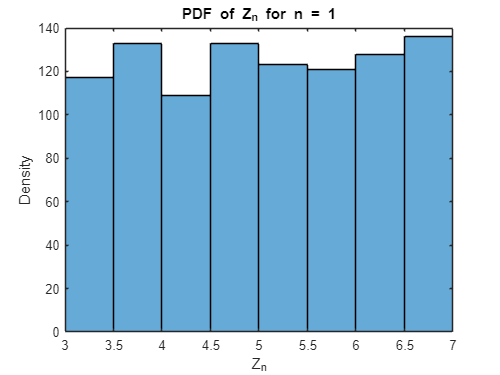

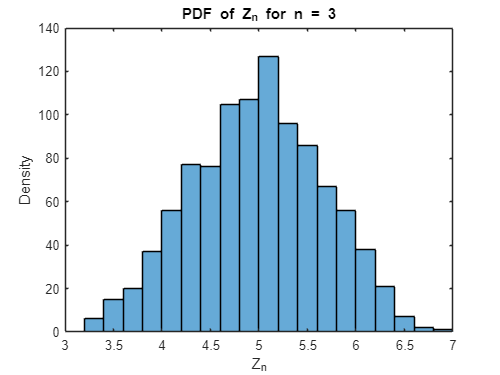

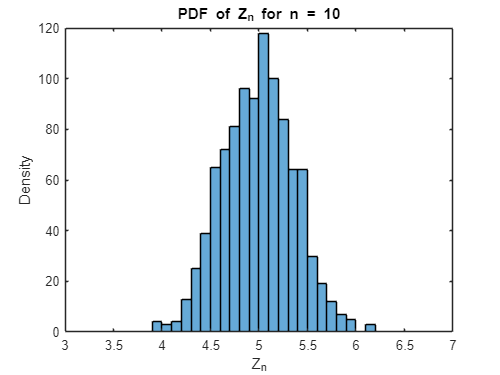

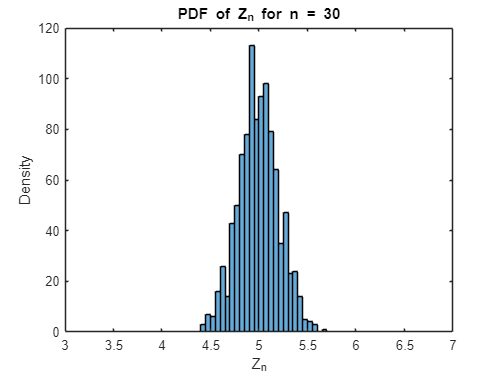

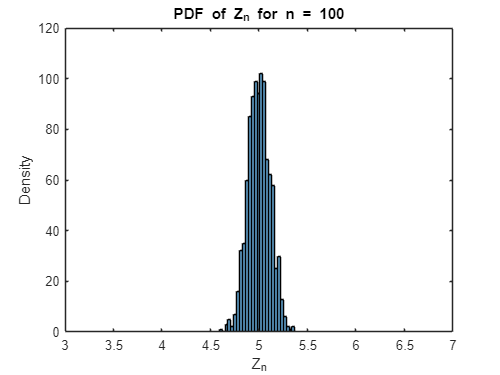

%Q4a
n_values = [1,3,10,30,100];
samples = 1000;
Zn(samples) = 0;
for k = 1:length(n_values)
    n = n_values(k);
    Zn(samples) = 0; 
    for i = 1:samples 
        Xi = 3 + 4*rand(n, 1);
        Zn(i) = 1/n*sum(Xi);
    end    
    figure;    
    histogram(Zn);
    title(['PDF of Z_n for n = ', num2str(n)]);
    xlabel('Z_n');
    ylabel('Density');
    xlim([3 7]);
end

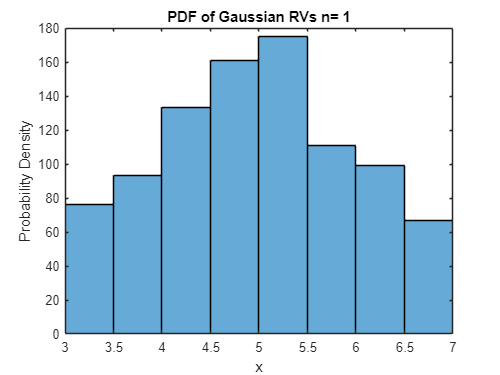

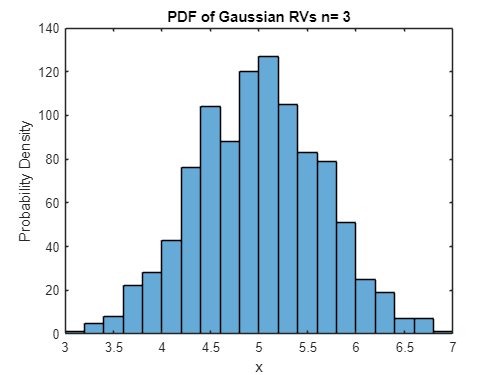

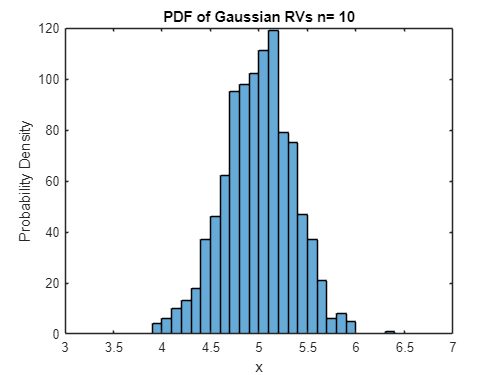

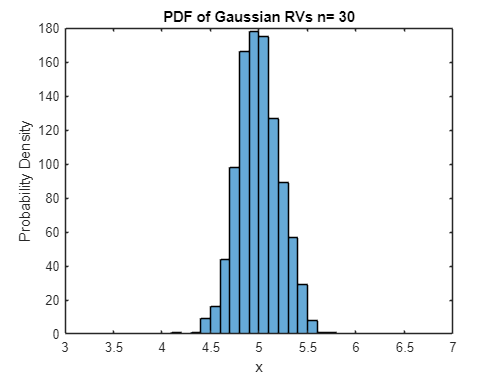

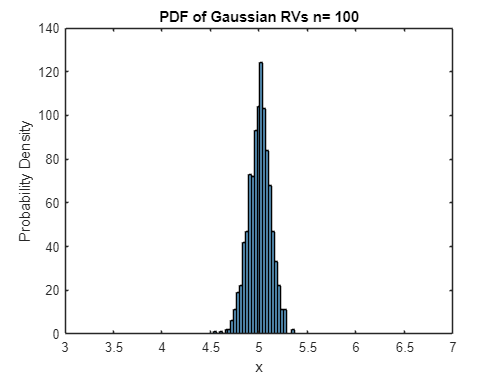


%b
VAR(length(n_values))= 0;
for k = 1:length(n_values)
    n = n_values(k);
    VAR(k) = 1.33/n;
end

%c
mu = 5;
samples = 1000;  
for k = 1:length(n_values)
    n = n_values(k);
    sigma = sqrt(1.33/n);
    X = mu + sigma * randn(samples, 1);
    figure;    
    histogram(X);
    title(['PDF of Gaussian RVs n= ', num2str(n)]);
    xlabel('x');
    ylabel('Probability Density');
    xlim([3 7]);
end

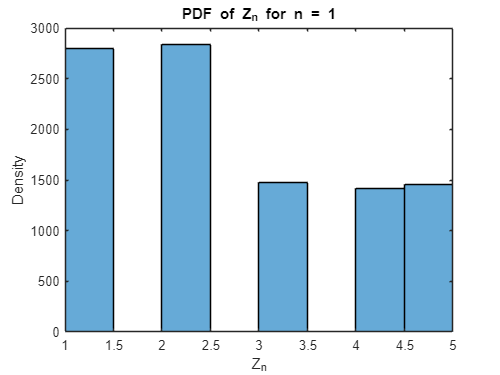

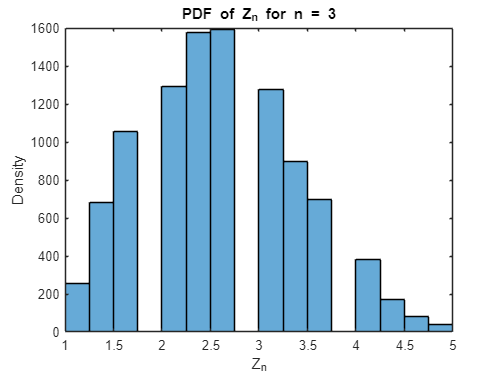

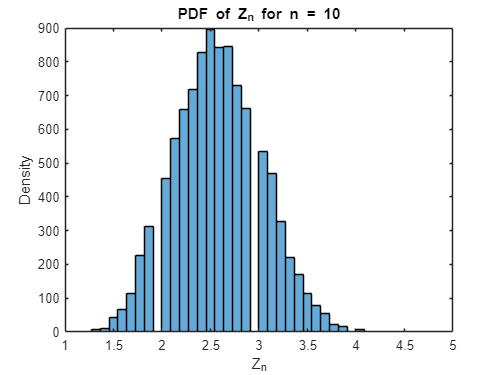

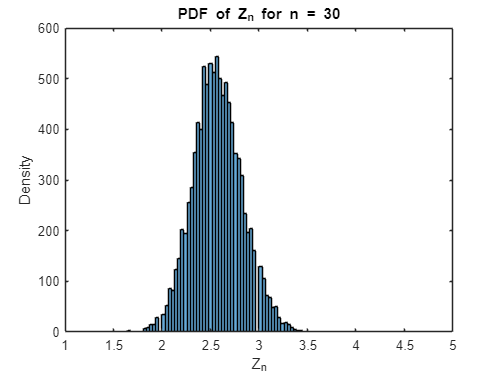

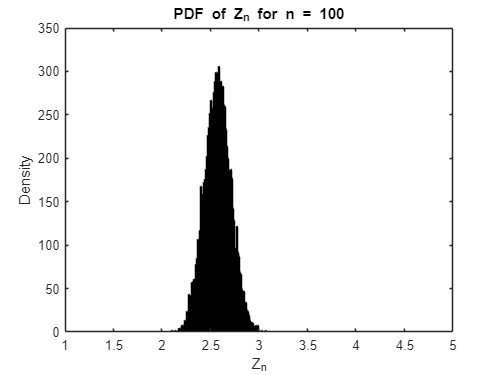

%Q4d - redo abc, fair 5-sided die that is described in Problem 1(d).
P = [2/7, 2/7, 1/7, 1/7, 1/7];

n_values = [1,3,10,30,100];
samples = 10000;
Zn(samples) = 0;
for k = 1:length(n_values)
    n = n_values(k);
    Zn(samples) = 0; 
    for i = 1:samples 
        Xi = randsample(1:5, n, true, P);
        Zn(i) = 1/n*sum(Xi);
    end    
    figure;    
    histogram(Zn, 'BinWidth', 1/(n+1));
    title(['PDF of Z_n for n = ', num2str(n)]);
    xlabel('Z_n');
    ylabel('Density');
    xlim([1 5]);
end

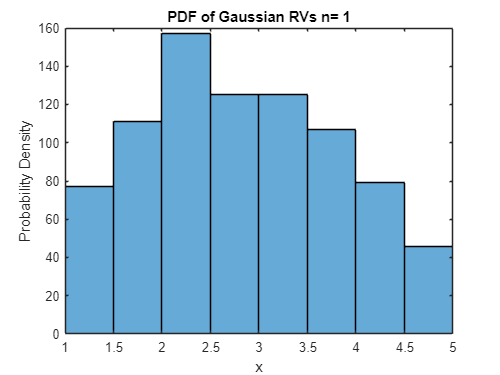

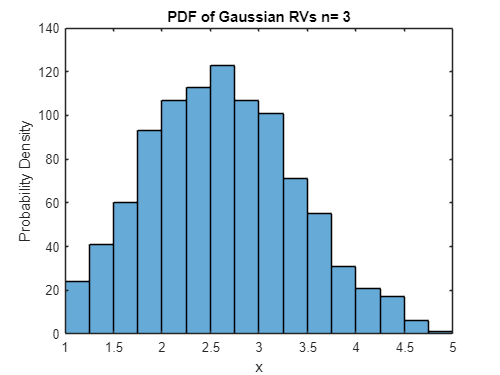

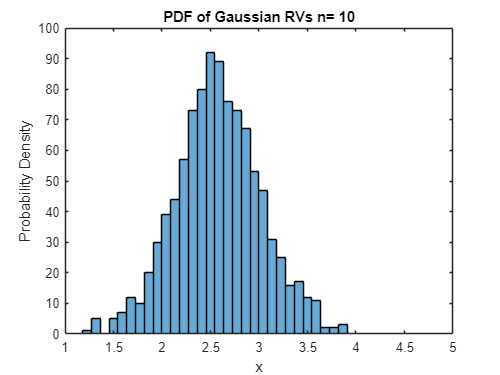

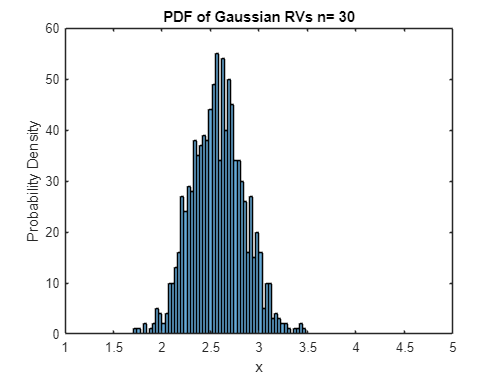

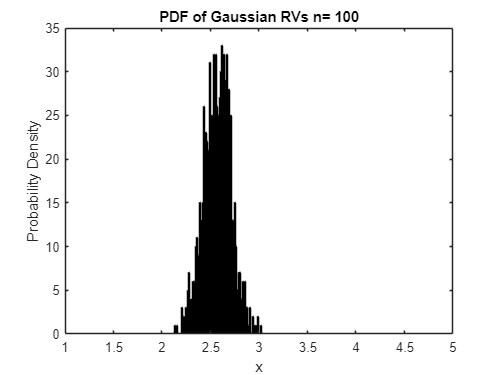


%b
VAR(length(n_values))= 0;
for k = 1:length(n_values)
    n = n_values(k);
    VAR(k) = 1.96/n;
end

%c
mu = 18/7;
samples = 1000;  
for k = 1:length(n_values)
    n = n_values(k);
    sigma = sqrt(96/(49*n));
    X = mu + sigma * randn(samples, 1);
    figure;    
    histogram(X, 'BinWidth', 1/(n+1));
    title(['PDF of Gaussian RVs n= ', num2str(n)]);
    xlabel('x');
    ylabel('Probability Density');
    xlim([1 5]);
end